# 3-24-2016 - This is an attempt to look at beta coherence/power at the beginning of a burst. DJC 

First thought is to use the burst tables. 

From the A_BuildStimTable 

%% build a burst table with the following

% 1 - burst id

% 2 - burst start sample

% 3 - burst stop sample

% 4 - nstims in burst (do last)

% 5 - type of conditioning (0 = falling, 1 = rising)

And from looking at bursts(:,1:20)

>> bursts(:,1:20)

ans =

  Columns 1 through 12

           1           2           3           4           5           6           7           8           9          10          11          12

      671573     1105718     1134583     1166430     1188135     1201492     1278904     1329848     1398056     1426226     1453844     1473416

      683829     1117865     1147991     1187178     1200380     1237056     1312877     1348098     1413344     1451401     1472463     1485575

           0           0           1           3           0           0           7           3           1           3           3           0

           2           2           1           0           2           2           1           0           0           1           1           2

  Columns 13 through 20

          13          14          15          16          17          18          19          20

     1486602     1502528     1524625     1539185     1552431     1600347     1624181     1649568

     1501525     1519215     1538145     1551375     1599331     1619024     1636635     1664926

           2           2           1           1           7           0           0           2

           1           0           1           1           0           2 

close all; clear all;clc
cd 'C:\Users\David\Desktop\Research\RaoLab\MATLAB\Code\Experiment\BetaTriggeredStim'
Z_Constants;
addpath ./scripts/ %DJC edit 7/20/2015;


SIDS = SIDS(8);

sid = SIDS{1}

sid = 0b5a2e

%DJC edited 7/20/2015 to fix tp paths
switch(sid)
    case '8adc5c'
        % sid = SIDS{1};
        tp = 'D:\Subjects\8adc5c\data\D6\8adc5c_BetaTriggeredStim';
        block = 'Block-67';
        stims = [31 32];
        chans = [8 7 48];
    case 'd5cd55'
        % sid = SIDS{2};
        tp = 'D:\Subjects\d5cd55\data\D8\d5cd55_BetaTriggeredStim';
        block = 'Block-49';
        stims = [54 62];
        chans = [53 61 63];
    case 'c91479'
        % sid = SIDS{3};
        tp = 'D:\Subjects\c91479\data\d7\c91479_BetaTriggeredStim';
        block = 'BetaPhase-14';
        stims = [55 56];
        chans = [64 63 48];
    case '7dbdec'
        % sid = SIDS{4};
        tp = 'D:\Subjects\7dbdec\data\d7\7dbdec_BetaTriggeredStim';
        block = 'BetaPhase-17';
        stims = [11 12];
        chans = [4 5 14];
    case '9ab7ab'
        %             sid = SIDS{5};
        tp = 'D:\Subjects\9ab7ab\data\d7\9ab7ab_BetaTriggeredStim';
        block = 'BetaPhase-3';
        stims = [59 60];
        chans = [51 52 53 58 57];
        % chans = 29;
    case '702d24'
        tp = 'D:\Subjects\702d24\data\d7\702d24_BetaStim';
        block = 'BetaPhase-4';
        stims = [13 14];
        chans = [4 5 21];
    case 'ecb43e' % added DJC 7-23-2015
        tp = 'D:\Subjects\ecb43e\data\d7\BetaStim';
        block = 'BetaPhase-3';
        stims = [56 64];
        chans = [47 55];
    case '0b5a2e' % added DJC 7-23-2015
        tp = 'D:\Subjects\0b5a2e\data\d8\0b5a2e_BetaStim\0b5a2e_BetaStim';
        block = 'BetaPhase-2';
        stims = [22 30];
        %             chans = [23 31 21 14 15 32 40];
        % DJC 2-5-2016 - prototype just on channel 23
        chans = [1:64];
        chans = [23];
        %                         chans = [23];
        %             chans = [14 15 23 24 26 33 34 35 39 40 42 43];
    case '0b5a2ePlayback' % added DJC 7-23-2015
        tp = 'D:\Subjects\0b5a2e\data\d8\0b5a2e_BetaStim\0b5a2e_BetaStim';
        block = 'BetaPhase-4';
        stims = [22 30];
        %             chans = [23 31 21 14 15 32 40];
        %             chans = [23 31];
        %             chans = 23;
        chans = [1:64];
        %             chans = 40;
        
    otherwise
        error('unknown SID entered');
end

chans(ismember(chans, stims)) = [];

tank = TTank;
tank.openTank(tp);
tank.selectBlock(block);


sid = '0b5a2e'

sid = 0b5a2e

load(fullfile(META_DIR, [sid '_tables_modDJC.mat']), 'bursts', 'fs', 'stims');
% drop any stims that happen in the first 500 milliseconds
stims(:,stims(2,:) < fs/2) = [];

% drop any probe stimuli without a corresponding pre-burst/post-burst
bads = stims(3,:) == 0 & (isnan(stims(4,:)) | isnan(stims(6,:)));
stims(:, bads) = [];

% select channels
chans = [14,21,23,31];
signal = [];

for chan = chans
    
    %% load in ecog data for that channel
    fprintf('loading in ecog data:\n');
    fprintf('channel %d:\n',chan);
    
    tic;
    grp = floor((chan-1)/16);
    ev = sprintf('ECO%d', grp+1);
    achan = chan - grp*16;
    
    %         [eco, efs] = tdt_loadStream(tp, block, ev, achan);
    [eco, info] = tank.readWaveEvent(ev, achan);
    efs = info.SamplingRateHz;
    eco = eco';
    
    toc;
    
    fac = fs/efs;
    
    sts = round(bursts(2,:) / fac);
    
    % 200 ms before to 0 when burst starts?
    presamps = round(0.2*efs);
    postsamps = round(-0.005*efs);
    
    temp = squeeze(getEpochSignal(eco', sts-presamps, sts+postsamps+1));
    t = (-presamps:postsamps)/efs;

    sig{chan} = temp;
    
end

loading in ecog data:


channel 14:


Elapsed time is 0.745276 seconds.


loading in ecog data:


channel 21:


Elapsed time is 0.682565 seconds.


loading in ecog data:


channel 23:


Elapsed time is 0.654358 seconds.


loading in ecog data:


channel 31:


Elapsed time is 0.706185 seconds.


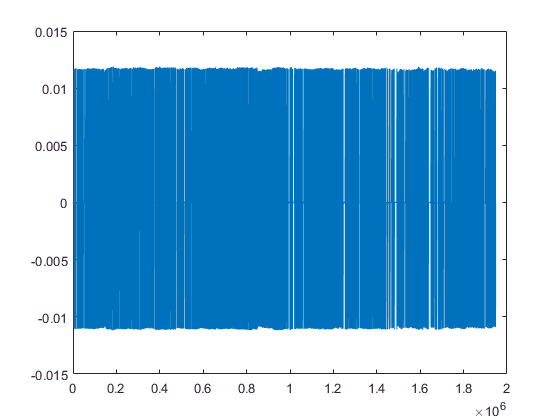

figure
tempLong = sig{23}(:);
plot(tempLong)

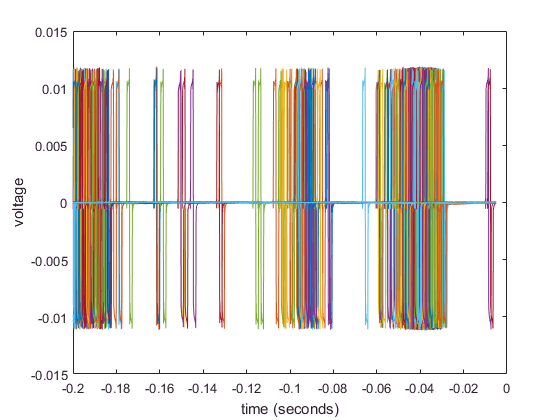

figure
plot(t,sig{23})
ylabel('voltage') 
xlabel('time (seconds)')